Colin Keenan

ECE 5470

2-17-2020

# Homework 3

1.  Histogram Equalization

## Compute Histogram of an image

clear

fprintf("Question 1, Part b:")

Question 1, Part b:

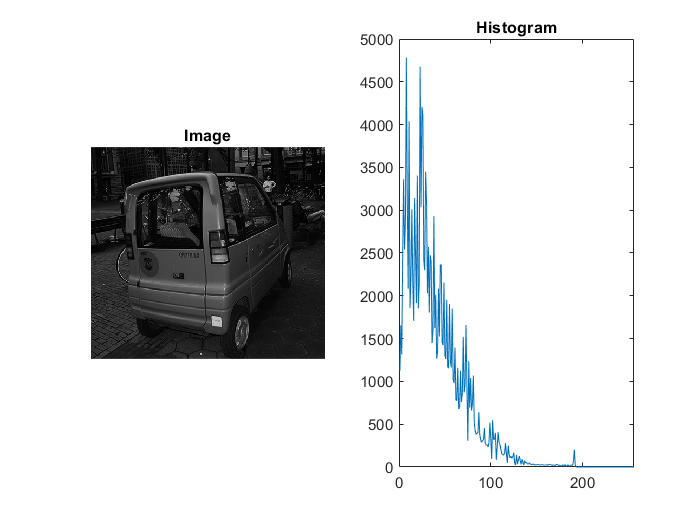


image = imread('Fig3-1.jpg');

hist = zeros(256,1);

for i = 1:size(image,1)
    for j = 1:size(image,2)
        r = image(i,j);
        hist(r+1) = hist(r+1) + 1;
    end
end

figure();
subplot(1,2,1)
imshow(image);
title("Image");
subplot(1,2,2)
plot(hist);
xlim([0 256]);
title("Histogram");

Explanation: The code above looks at each pixel and determines the level of intesity. Then in an array spanning the values of intensities, in the case of 8-bit depth, 256 values from 0-255, but since MATLAB starts at index 1, an the value at the index of that intensity is incremented. This clearly shows that the image out of the box is heavily favored towards the dark end of the spectrum.

## Use Histogram Equalization on image Fig3-1.jpg

clear

fprintf("Question 1, Part c,d:")

Question 1, Part c,d:

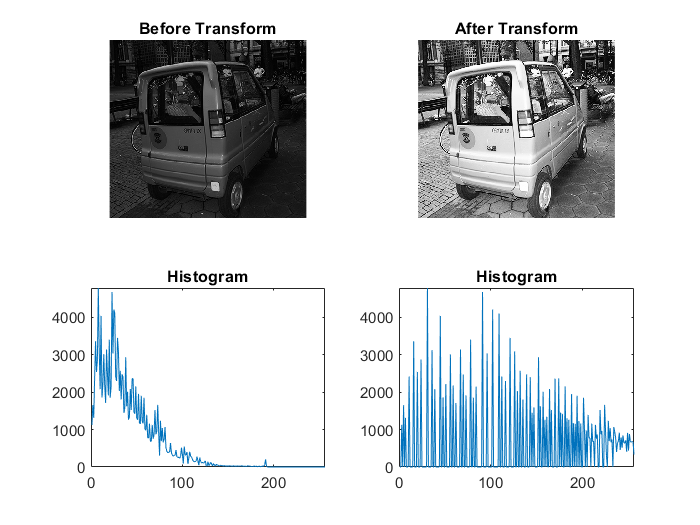


file = 'Fig3-1.jpg';
image = imread(file);

hist = histogram(image);
prob = hist ./ (size(image,1) * size(image,2));

info = imfinfo(file);
bits = info.BitDepth;
levels = 2^bits;

image_mod = zeros(size(image));

for i = 1:size(image,1)
    for j = 1:size(image,2)
        level = image(i,j);        
        prob_sum = summation(prob,1,level);
        new_level = (levels-1) * prob_sum;
        image_mod(i,j) = round(new_level) / 255;
    end
end

hist_mod = histogram(image_mod .* 255);

figure();
subplot(2,2,1)
imshow(image);
title("Before Transform");
subplot(2,2,2)
imshow(image_mod);
title("After Transform");
subplot(2,2,3)
plot(hist);
xlim([0 256]);
title("Histogram");
subplot(2,2,4)
plot(hist_mod);
xlim([0 256]);
title("Histogram");

Explanation: This code takes the histogram of the image and attempts to evenly split each value across the entire spectrum 0-255, in the case of 8-bit depth. This is done by getting the number of times a certain intensity is used, and generating a probability function of those intensities. Then the new level is generated by multiplying the possible levels minus 1 by the cumulative probability of that level starting at level 0 and then rounding since each level is discrete. As you can see in the output image, it is much brighter and a lot of the darker details are clear now, such as the cobblestone road, and the sidewalk.

2.  Smoothing Spacial Filtering

## Smoothing Spacial Filtering with masks of 3x3 and 5x5 with coefficients of 1

clear

fprintf("Question 2, Part a,b,c:")

Question 2, Part a,b,c:

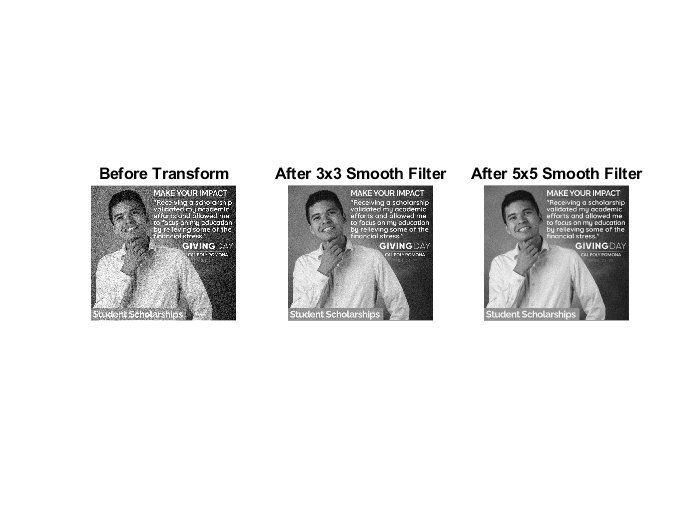


file = 'donation.tif';
image = imread(file);
image_double = im2double(image);

image_mod_3x3 = zeros(size(image_double));
image_mod_5x5 = zeros(size(image_double));


mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
weight_3x3 = sum(sum(mask_3x3));

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked_3x3 = frame_3x3 .* mask_3x3;
        new_level = sum(sum(masked_3x3)) / weight_3x3;
        image_mod_3x3(i,j) = new_level;
    end
end
        
mask_5x5 = [[1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]];
weight_5x5 = sum(sum(mask_5x5));

for i = 1+2 : size(image_double,1)-2
    for j = 1+2 : size(image_double,2)-2
        
        frame_5x5 = [[image_double(i-2,j-2) image_double(i-2,j-1) image_double(i-2,j+0) image_double(i-2,j+1) image_double(i-2,j+2)]
                     [image_double(i-1,j-2) image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1) image_double(i-1,j+2)]
                     [image_double(i+0,j-2) image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1) image_double(i+0,j+2)]
                     [image_double(i+1,j-2) image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1) image_double(i+1,j+2)]
                     [image_double(i+2,j-2) image_double(i+2,j-1) image_double(i+2,j+0) image_double(i+2,j+1) image_double(i+2,j+2)]];
        
        masked_5x5 = frame_5x5 .* mask_5x5;
        new_level = sum(sum(masked_5x5)) / weight_5x5;
        image_mod_5x5(i,j) = new_level;
    end
end

figure();
subplot(1,3,1)
imshow(image);
title("Before Transform");
subplot(1,3,2)
imshow(image_mod_3x3);
title("After 3x3 Smooth Filter");
subplot(1,3,3)
imshow(image_mod_5x5);
title("After 5x5 Smooth Filter");

Explanation: This code provides basic smoothing with a 3x3 and 5x5 masks filled with equal weights of 0. In effect for each new pixel, all 8 pixels around it, along with the original are averaged and that average is the new value. The 3x3 mask appears to be the winner in this instance due to smoothing out some of the grain, but also does not take away a great deal of detail from the image.

## Perform Spatial Filtering and thresholding on Fig3-2b.tif

clear

fprintf("Question 2, Part a,b,c:")

Question 2, Part a,b,c:

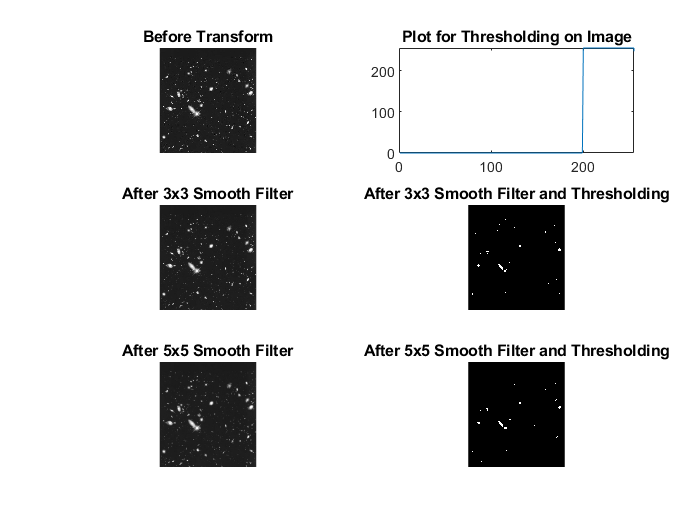


file = 'Fig3-2b.tif';
image = imread(file);
image_double = im2double(image);

% Spatial Filtering

image_mod_3x3 = zeros(size(image_double));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
weight_3x3 = sum(sum(mask_3x3));

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked_3x3 = frame_3x3 .* mask_3x3;
        new_level = sum(sum(masked_3x3)) / weight_3x3;
        image_mod_3x3(i,j) = new_level;
    end
end

mask_5x5 = [[1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]
            [1 1 1 1 1]];
weight_5x5 = sum(sum(mask_5x5));

for i = 1+2 : size(image_double,1)-2
    for j = 1+2 : size(image_double,2)-2
        
        frame_5x5 = [[image_double(i-2,j-2) image_double(i-2,j-1) image_double(i-2,j+0) image_double(i-2,j+1) image_double(i-2,j+2)]
                     [image_double(i-1,j-2) image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1) image_double(i-1,j+2)]
                     [image_double(i+0,j-2) image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1) image_double(i+0,j+2)]
                     [image_double(i+1,j-2) image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1) image_double(i+1,j+2)]
                     [image_double(i+2,j-2) image_double(i+2,j-1) image_double(i+2,j+0) image_double(i+2,j+1) image_double(i+2,j+2)]];
        
        masked_5x5 = frame_5x5 .* mask_5x5;
        new_level = sum(sum(masked_5x5)) / weight_5x5;
        image_mod_5x5(i,j) = new_level;
    end
end

% Thresholding

upper_range = 255/255;
lower_range = 200/255;

transform = 1:256;
for x = 1:256
    if((x >= lower_range*255) && (x <= upper_range*255))
        transform(x) = 255;
    else
        transform(x) = 0;
    end
end

image_mod_thresh_3x3 = zeros(size(image_mod_3x3));

for i = 1:size(image_mod_3x3,1)
    for j = 1:size(image_mod_3x3,2)
        r = image_mod_3x3(i,j);
        if((r >= lower_range) && (r <= upper_range))
            image_mod_thresh_3x3(i,j) = 1;
        else
            image_mod_thresh_3x3(i,j) = 0;
        end
    end
end

image_mod_thresh_5x5 = zeros(size(image_mod_5x5));

for i = 1:size(image_mod_5x5,1)
    for j = 1:size(image_mod_5x5,2)
        r = image_mod_5x5(i,j);
        if((r >= lower_range) && (r <= upper_range))
            image_mod_thresh_5x5(i,j) = 1;
        else
            image_mod_thresh_5x5(i,j) = 0;
        end
    end
end

figure();
subplot(3,2,1)
imshow(image);
title("Before Transform");
subplot(3,2,2)
plot(transform);
xlim([0,255]);
ylim([0,255]);
title("Plot for Thresholding on Image");
subplot(3,2,3)
imshow(image_mod_3x3);
title("After 3x3 Smooth Filter");
subplot(3,2,4)
imshow(image_mod_thresh_3x3);
title("After 3x3 Smooth Filter and Thresholding");
subplot(3,2,5)
imshow(image_mod_5x5);
title("After 5x5 Smooth Filter");
subplot(3,2,6)
imshow(image_mod_thresh_5x5);
title("After 5x5 Smooth Filter and Thresholding");

Explanation: This code applies a smoothing filter in both 5x5 and 3x3 variants to a outer space picture with the goal of eliminating small celestial objects while keeping the large ones intact. Then a threshold filter is applie to the image to clearly define the differences between large celestial bodies and small bodies along with noise.

3.  Order-Statistics Filters

## 3x3 Median, Max, and Min Filters to image Fig3-3.tif

clear

fprintf("Question 3, Part a,b:")

Question 3, Part a,b:

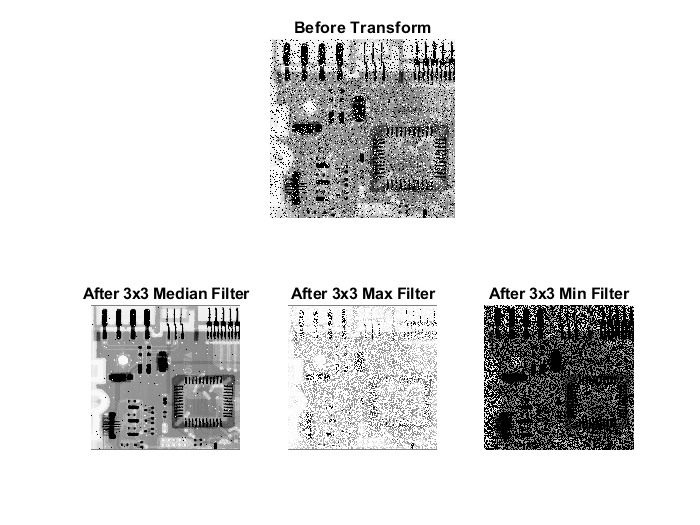


file = 'Fig3-3.tif';
image = imread(file);
image_double = im2double(image);

image_mod_median = zeros(size(image_double));
image_mod_max    = zeros(size(image_double));
image_mod_min    = zeros(size(image_double));

% Median, Max, and Min Filters
for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
                 
        median_level = median(median(frame_3x3));
        max_level = max(max(frame_3x3));
        min_level = min(min(frame_3x3));
        
        image_mod_median(i,j) = median_level;
        image_mod_max(i,j)    = max_level;
        image_mod_min(i,j)    = min_level;
    end
end

figure();
subplot(2,3,[1 2 3])
imshow(image);
title("Before Transform");
subplot(2,3,4)
imshow(image_mod_median);
title("After 3x3 Median Filter");
subplot(2,3,5)
imshow(image_mod_max);
title("After 3x3 Max Filter");
subplot(2,3,6)
imshow(image_mod_min);
title("After 3x3 Min Filter");

Explanation: This code applies median, max, and min filters in the 3x3 mask variant, where for every pixel, it gets the median, max, or min pixel intensity of it and its surrounding 8 pixels and that is the new value for the pixel. The median filter is the clear winner in this case as it is the clearest without modifcation of the original image by arithmetic means, due to the fact that if the majority of the pixels in the mask are pixels related to the original image, then regardless of any noise, that original image's intensity will remain. The max filter highlights the "pepper" noise, blacker intensity noise, and can be used to subtract from the main image to delete some of the nosie. The min filter on the other hand highlights the "salt" noise, whiter intensity noise, and again can be used in conjunction with the original image to eliminate some noise.

## Apply 5x5 media, max, and min filters and see changes

clear

fprintf("Question 3, Part c:")

Question 3, Part c:

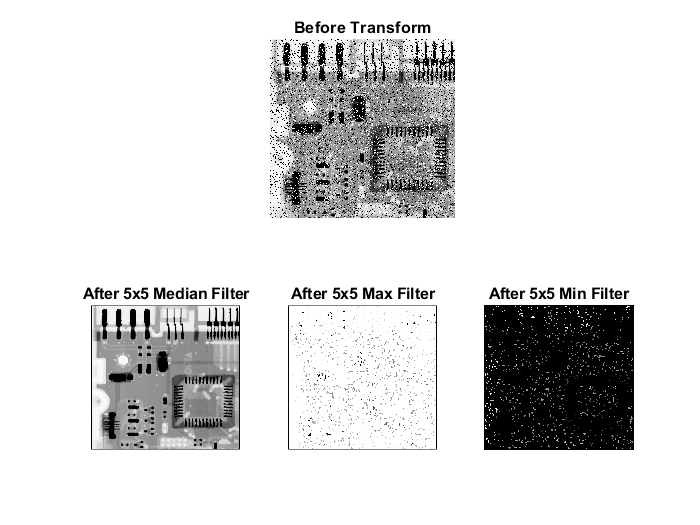


file = 'Fig3-3.tif';
image = imread(file);
image_double = im2double(image);

image_mod_median = zeros(size(image_double));
image_mod_max    = zeros(size(image_double));
image_mod_min    = zeros(size(image_double));

% Median, Max, and Min Filters
for i = 1+2 : size(image_double,1)-2
    for j = 1+2 : size(image_double,2)-2
        frame_5x5 = [[image_double(i-2,j-2) image_double(i-2,j-1) image_double(i-2,j+0) image_double(i-2,j+1) image_double(i-2,j+2)]
                     [image_double(i-1,j-2) image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1) image_double(i-1,j+2)]
                     [image_double(i+0,j-2) image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1) image_double(i+0,j+2)]
                     [image_double(i+1,j-2) image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1) image_double(i+1,j+2)]
                     [image_double(i+2,j-2) image_double(i+2,j-1) image_double(i+2,j+0) image_double(i+2,j+1) image_double(i+2,j+2)]];
        
        median_level = median(median(frame_5x5));
        max_level = max(max(frame_5x5));
        min_level = min(min(frame_5x5));
        
        image_mod_median(i,j) = median_level;
        image_mod_max(i,j)    = max_level;
        image_mod_min(i,j)    = min_level;
    end
end

figure();
subplot(2,3,[1 2 3])
imshow(image);
title("Before Transform");
subplot(2,3,4)
imshow(image_mod_median);
title("After 5x5 Median Filter");
subplot(2,3,5)
imshow(image_mod_max);
title("After 5x5 Max Filter");
subplot(2,3,6)
imshow(image_mod_min);
title("After 5x5 Min Filter");

Explanation: This code applies the same statistical filters as shown previously, but with a mask size of 5x5, which in effect gives the new pixel more data to compare, which depending on the image is good or bad. In this case it is good, especially in the case of the median filter which results in almost no noise left in the image, but finer details of certain traces are lost.

## APPENDIX

function hist = histogram(image)
% Histogram generates an array containing the occurances at each intensity 
% value of a given image input, image must be 8 bit with integer intensities 
% from 0-256
    hist = zeros(256,1);

    for i = 1:size(image,1)
        for j = 1:size(image,2)
            r = image(i,j);
            hist(r+1) = hist(r+1) + 1;
        end
    end
end

function sum = summation(array, from, to)
%Summation calculates the summation from 'from' to 'to' in array 'array'
    sum = 0;
    for i = from:to+1
        sum = sum + array(i);
    end
end